# **LAB1**

The following code is for Question1-6.

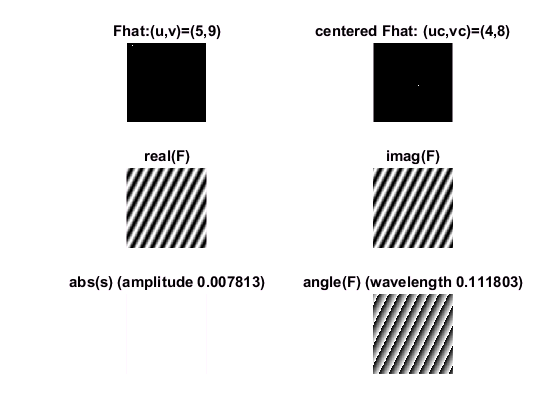

addpath('DD2423_Lab_Files/Functions')
addpath('DD2423_Lab_Files/Images')

figure(1)
fftwave(5,9);

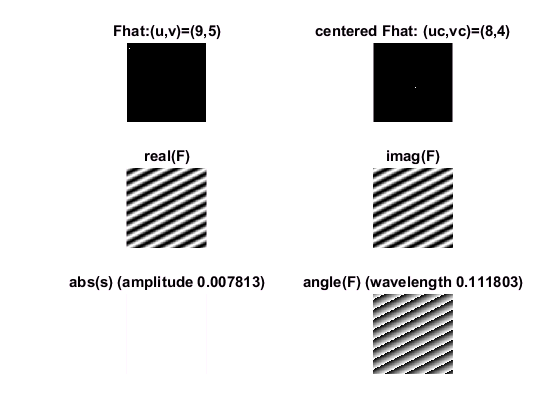


figure(2)
fftwave(9,5)

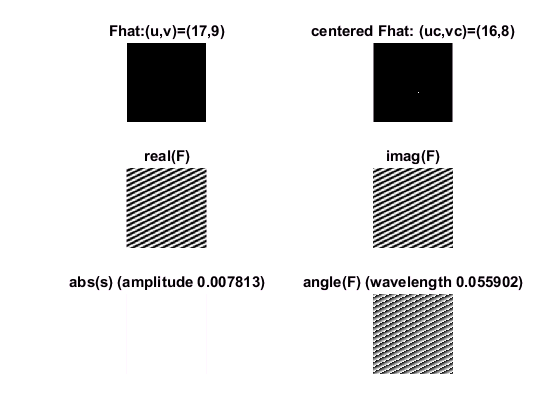


figure(3)
fftwave(17,9)

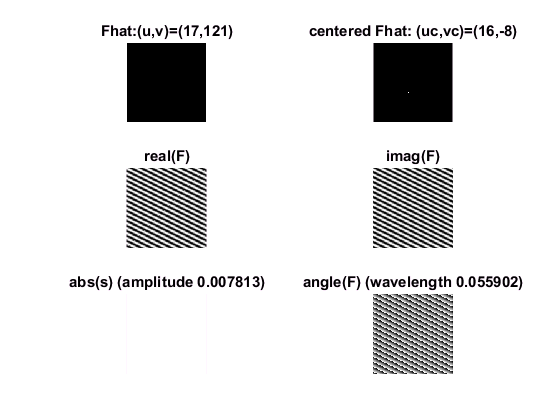


figure(4)
fftwave(17,121)

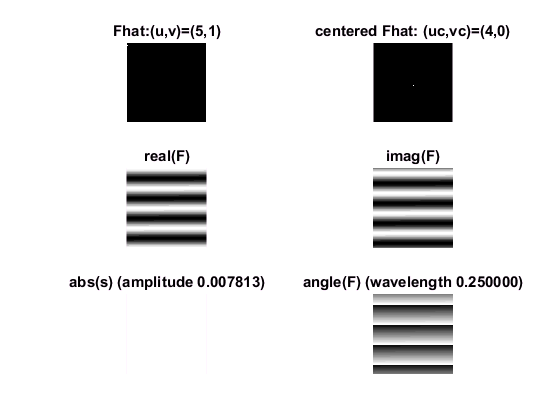


figure(5)
fftwave(5,1)

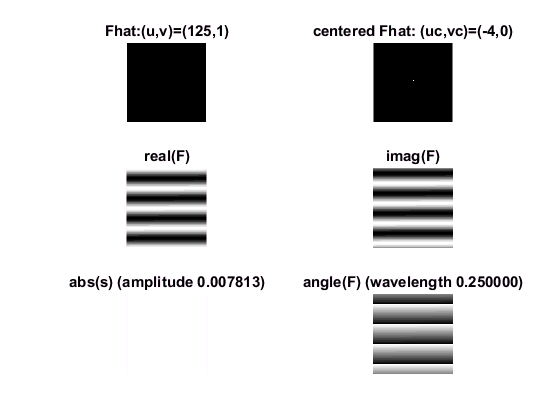


figure(6)
fftwave(125,1)

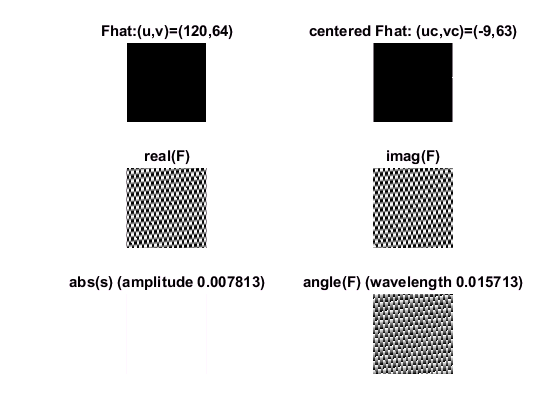


figure(7)
fftwave(120,64)  %Question 5


figure(8)
fftwave(35,64)  %Question 5

The following Code is for Question7-9(Linearity)

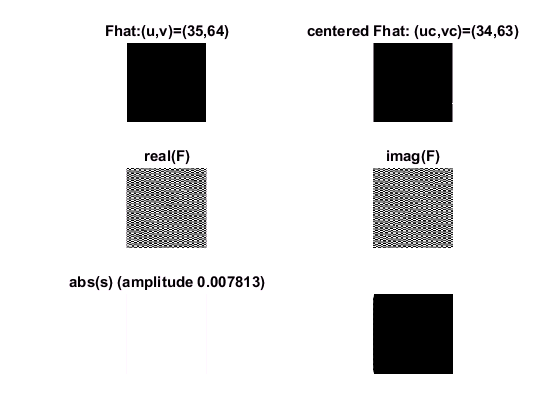

F = [ zeros(56, 128); ones(16, 128); zeros(56, 128)];
G = F';
H = F + 2 * G;

Fhat = fft2(F);
Ghat = fft2(G);
Hhat = fft2(H);

showgrey(abs(Fhat));

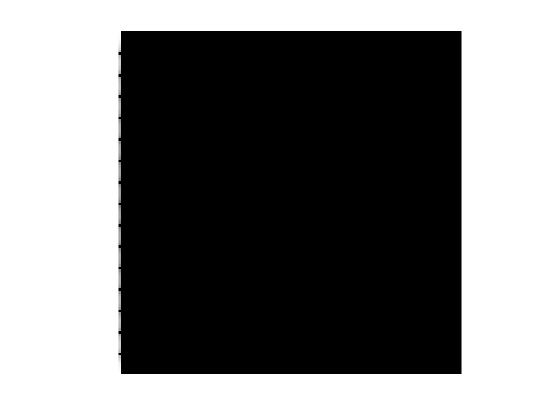

figure(9)
showgrey(log(1 + abs(Fhat)));

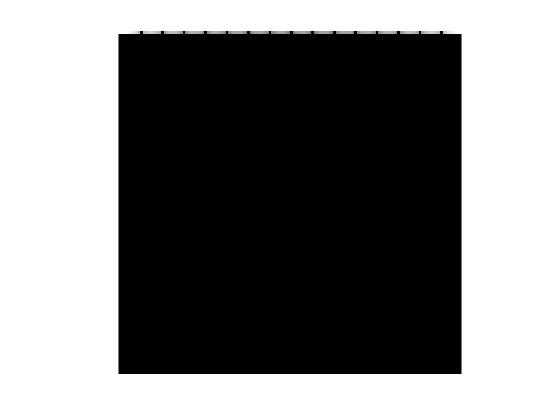


figure(10)
showgrey(log(1 + abs(Ghat)));

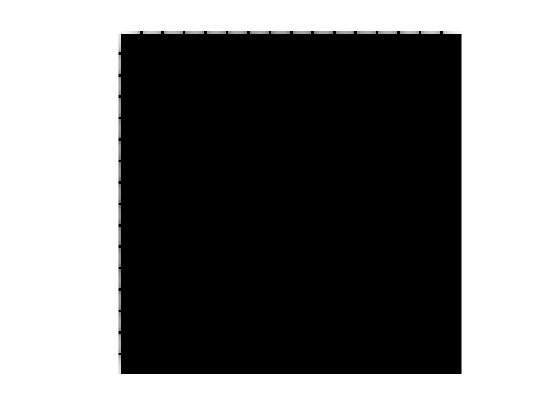


figure(11)
showgrey(log(1 + abs(Hhat)));

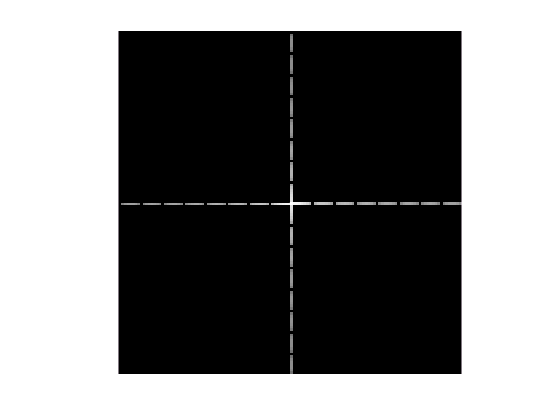


figure(12)
showgrey(log(1 + abs(fftshift(Hhat))));

The following code deals with Question 10

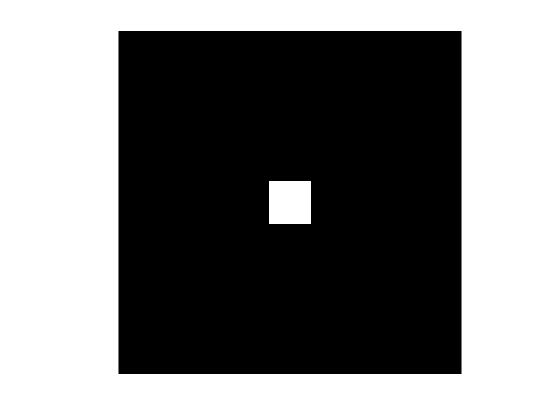

F=[zeros(56,128);ones(16,128);zeros(56,128)];
G=F';
K=F.*G;

figure(13);
showgrey(K);

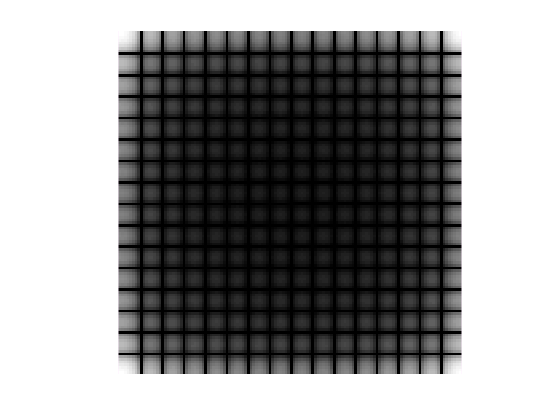


figure(14);
showgrey(log( 1 + abs(fft2(K))));

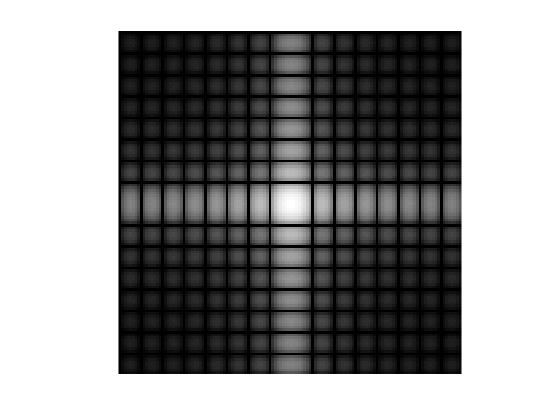



figure(15);
showfs(fft2(F.*G));


%otherway round

% Now treating F and G 
% in Fourier Domain

K=K*(128^2);
figure(16);
showgrey(log( 1 + abs(ifft2(K))));


figure(17);
showfs(ifft2(K));

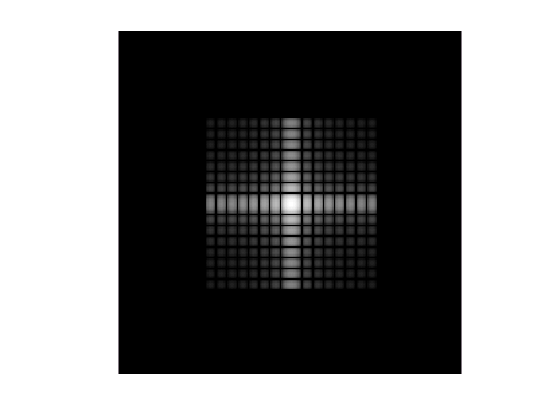


%Second Way

F1=fftshift(fft2(F));
F2=fftshift(fft2(G));

C=conv2(F1,F2)*(1/(128)^2);

figure(18);
showgrey(log(1+abs(C)));

The following section deals with Qurstion11(Scaling)

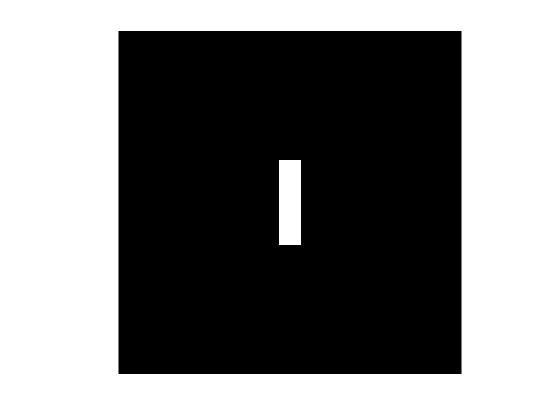

F = [zeros(48, 128); ones(32, 128); zeros(48, 128)] .* ...
[zeros(128, 60) ones(128, 8) zeros(128, 60)];

figure(19);
showgrey(abs(F));

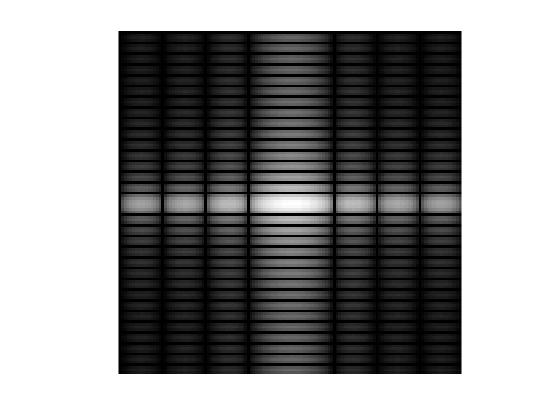



figure(20);
Fhat=fft2(F);
showfs(Fhat);

The following code deals with Question 12(Rotation)    

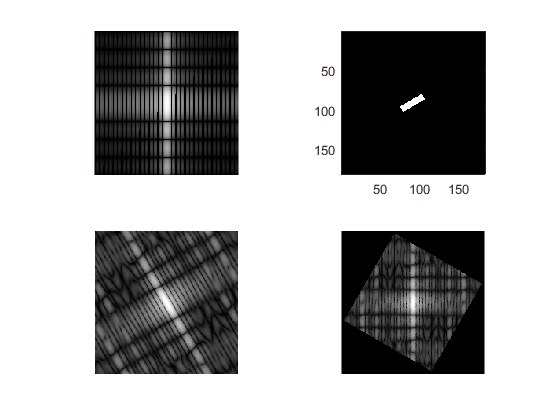

figure(21)
q12(30)

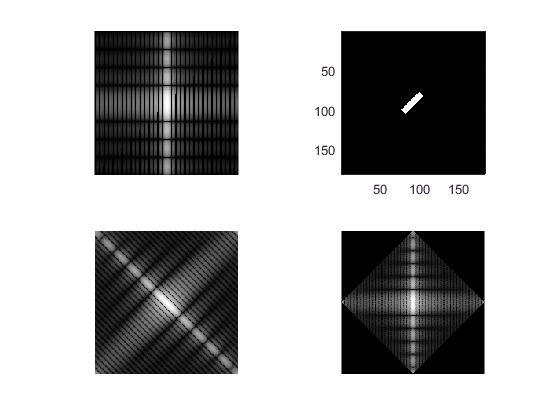


figure(22)
q12(45)

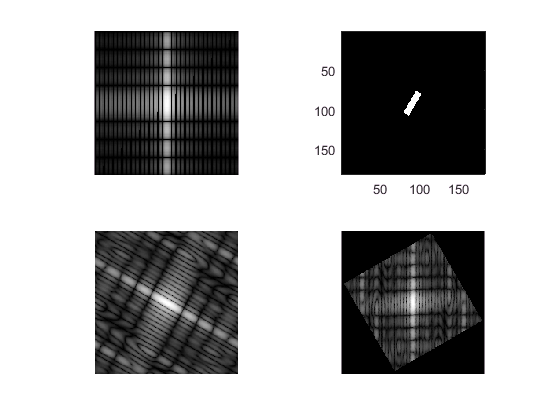


figure(23)
q12(60)

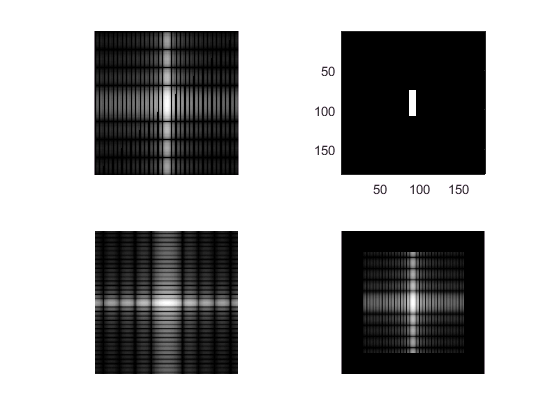


figure(24)
q12(90)

The following code deals with Question 13(Phase and Magnitude of FT)

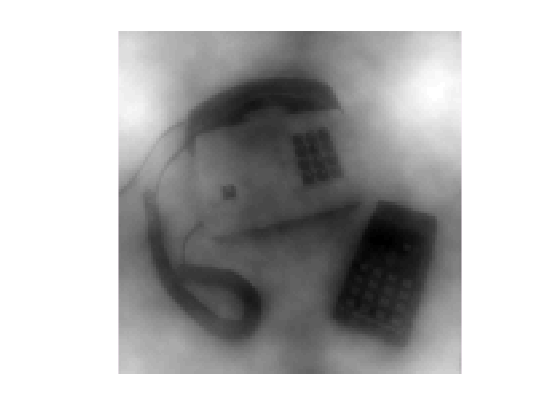

addpath('DD2423_Lab_Files/Images-m');
addpath('DD2423_Lab_Files/Functions');

figure(25);
img1=phonecalc128;
showgrey(pow2image(img1,10^-10));

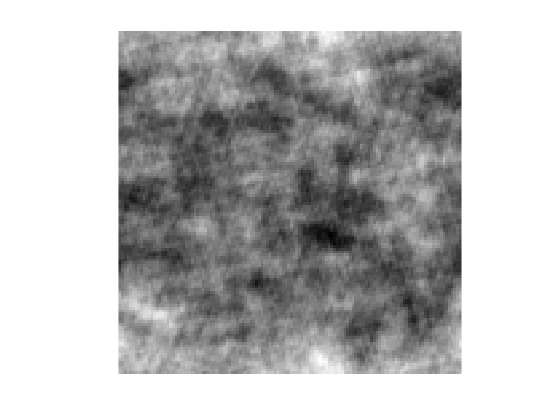


figure(26);
showgrey(randphaseimage(img1));

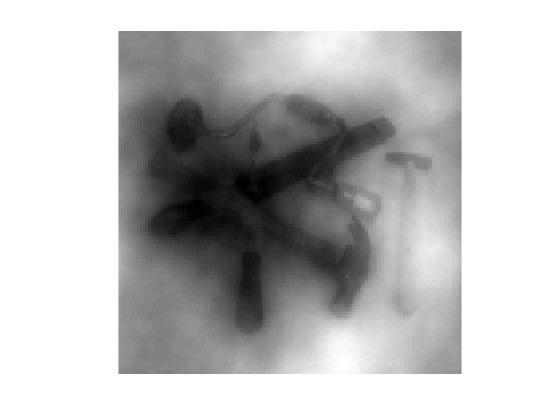


figure(27);
img2=few128;
showgrey(pow2image(img2,10^-10));

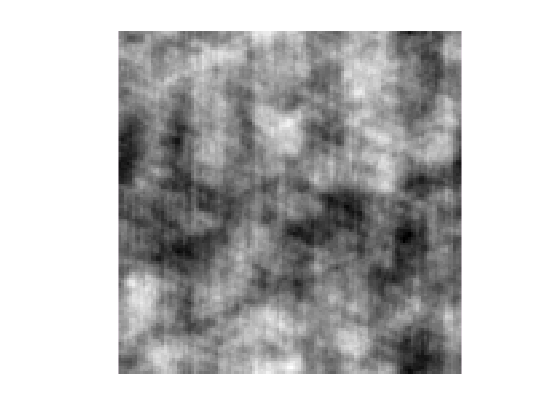


figure(28);
showgrey(randphaseimage(img2));

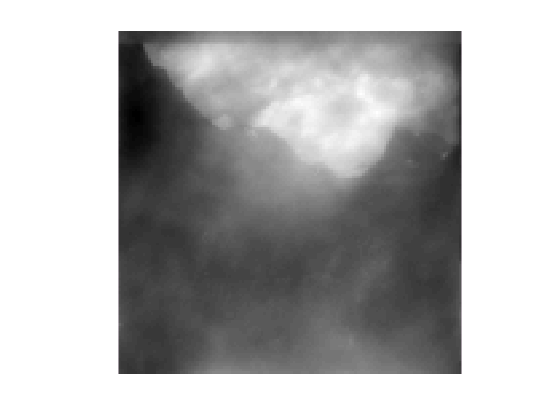


figure(29);
img3=nallo128;
showgrey(pow2image(img3,10^-10));

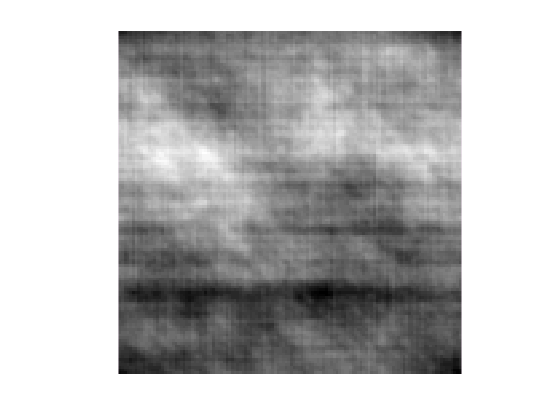


figure(30);
showgrey(randphaseimage(img3));

The following code deals with Question 14-15(Filtering)


% t values are 0.1, 0.3, 1.0, 10.0 and 100.0
pic=deltafcn(128,128);
figure(31)
subplot(3,2,1)
t1=gaussfft(pic,0.1);
showgrey(t1);
title(sprintf('t=0.1'))
var_t1=variance(t1)

var_t1 =     0.0133    0.0000
    0.0000    0.0133



subplot(3,2,2)
t2=gaussfft(pic,0.3);
showgrey(t2);
title(sprintf('t=0.3'))
var_t2=variance(t2)

var_t2 =     0.2811    0.0000
    0.0000    0.2811



subplot(3,2,3)
t3=gaussfft(pic,1.0);
showgrey(t3);
title(sprintf('t=1.0'))
var_t3=variance(t3)

var_t3 =     1.0000    0.0000
    0.0000    1.0000



subplot(3,2,4)
t4=gaussfft(pic,10.0);
showgrey(t4);
title(sprintf('t=10.0'))
var_t4=variance(t4)

var_t4 =    10.0000    0.0000
    0.0000   10.0000


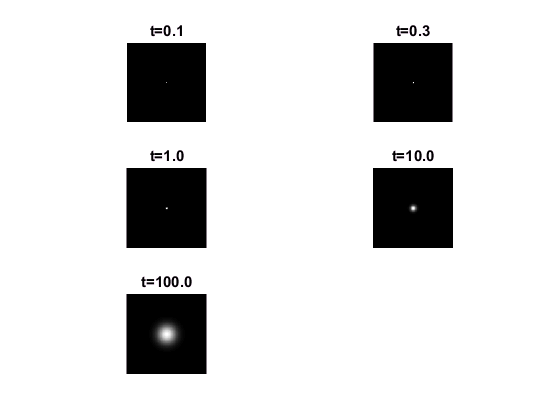


subplot(3,2,5)
t5=gaussfft(pic,100.0);
showgrey(t5);
title(sprintf('t=100.0'))

var_t5=variance(t5)

var_t5 =   100.0000    0.0000
    0.0000  100.0000




figure(32)

subplot(3,2,1)
showgrey(discgaussfft(pic,0.1));
title(sprintf('t=0.1'))
var_t6=variance(discgaussfft(pic,0.1))

var_t6 =     0.1000   -0.0000
   -0.0000    0.1000



subplot(3,2,2)
showgrey(discgaussfft(pic,0.3));
title(sprintf('t=0.3'))
var_t7=variance(discgaussfft(pic,0.3))

var_t7 =     0.3000   -0.0000
   -0.0000    0.3000



subplot(3,2,3)
showgrey(discgaussfft(pic,1.0));
title(sprintf('t=1.0'))
var_t8=variance(discgaussfft(pic,1.0))

var_t8 =     1.0000    0.0000
    0.0000    1.0000



subplot(3,2,4)
showgrey(discgaussfft(pic,10.0));
title(sprintf('t=10.0'))
var_t9=variance(discgaussfft(pic,10.0))

var_t9 =    10.0000   -0.0000
   -0.0000   10.0000


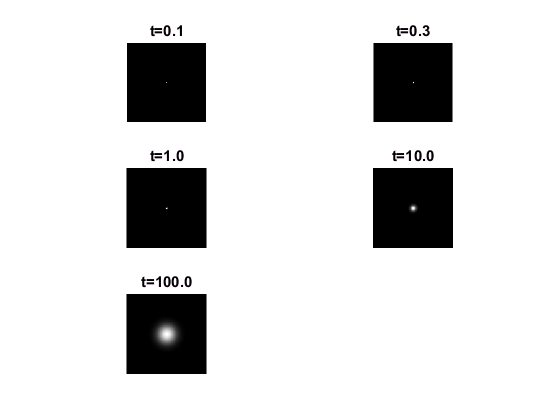


subplot(3,2,5)
showgrey(discgaussfft(pic,100.0));
title(sprintf('t=100.0'))

var_t10=variance(discgaussfft(pic,100.0))

var_t10 =   100.0000   -0.0000
   -0.0000  100.0000


The following program deals with Question 16(Gaussian Filter)

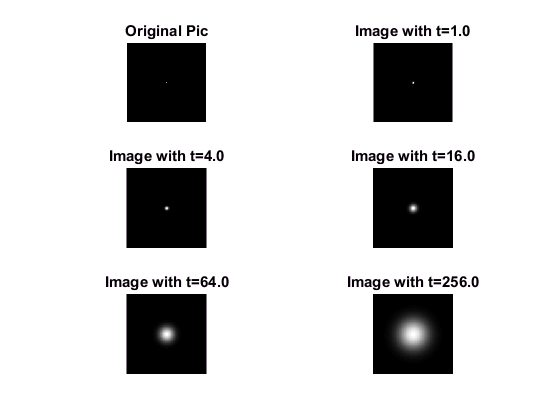

 
  figure(33)
  
  subplot(3,2,1)
  showgrey(pic);
  title("Original Pic");
  
  subplot(3,2,2)
  showgrey(gaussfft(pic,1));
  title("Image with t=1.0");
  
  subplot(3,2,3)
  showgrey(gaussfft(pic,4.0));
  title("Image with t=4.0");
  
  subplot(3,2,4);
  showgrey(gaussfft(pic,16.0));
  title("Image with t=16.0");
  
  subplot(3,2,5);
  showgrey(gaussfft(pic,64.0));
  title("Image with t=64.0");

  subplot(3,2,6);
  showgrey(gaussfft(pic,256.0));
  title("Image with t=256.0");

The following Code deals with Question 17-18(Smoothing)

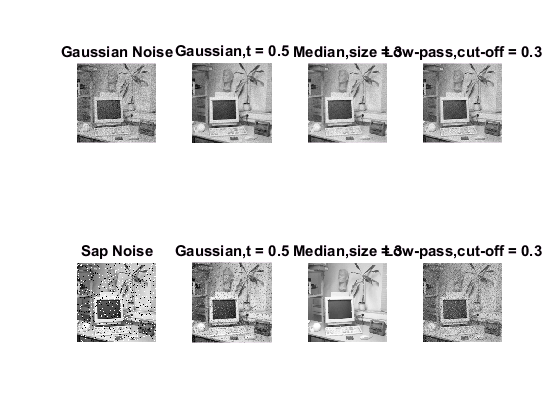

office = office256;
add = gaussnoise(office, 16); %With gauss noise
%Gaussian noise: each pixel randomized around its value with a standard
%deviation
sap = sapnoise(office, 0.1, 255); %With sap noise
%Salt and pepper noise: Random 0 and 1 pixels in image

%subplot(1,3,1);
%showgrey(office);
%title("Original image");
figure(34);
subplot(2,4,1);
showgrey(add);
title("Gaussian Noise");
subplot(2,4,5);
showgrey(sap);
title("Sap Noise");

add_gaussian = gaussfft(add, 0.5);
subplot(2,4,2);
showgrey(abs(add_gaussian));
title("Gaussian,t = 0.5");
add_median = medfilt(add,3);
subplot(2,4,3);
showgrey(add_median);
title("Median,size = 3");
add_lowpass = ideal(add,0.3); 
subplot(2,4,4);
showgrey(add_lowpass);
title("Low-pass,cut-off = 0.3");

sap_gaussian = gaussfft(sap, 0.5);
subplot(2,4,6);
showgrey(abs(sap_gaussian));
title("Gaussian,t = 0.5");
sap_median = medfilt(sap,3);
subplot(2,4,7);
showgrey(sap_median);
title("Median,size = 3");
sap_lowpass = ideal(sap,0.3); 
subplot(2,4,8);
showgrey(sap_lowpass);
title("Low-pass,cut-off = 0.3");

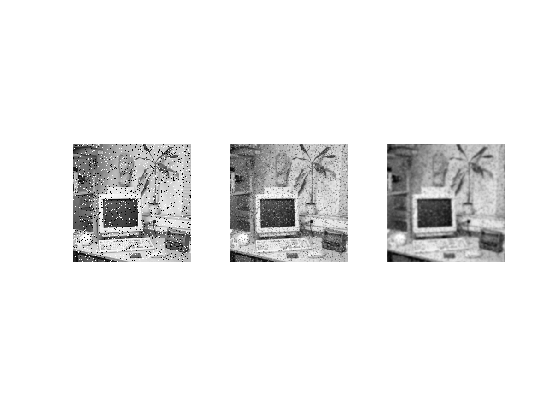


figure(35)
subplot(1,3,1);
showgrey(sap);
subplot(1,3,2);
showgrey(abs(sap_gaussian));
subplot(1,3,3);
showgrey(abs(gaussfft(sap,3)));

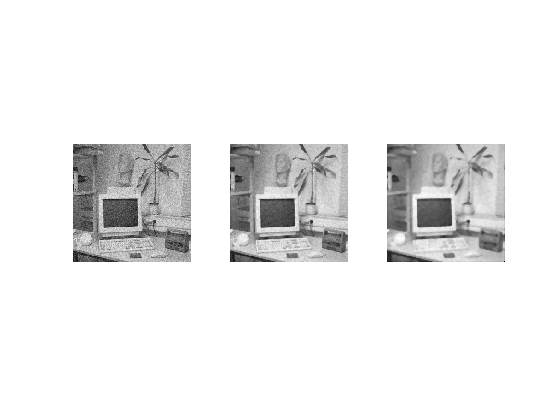



figure(36)
subplot(1,3,1);
showgrey(add);
subplot(1,3,2);
showgrey(add_median);
subplot(1,3,3);
showgrey(medfilt(add,6));

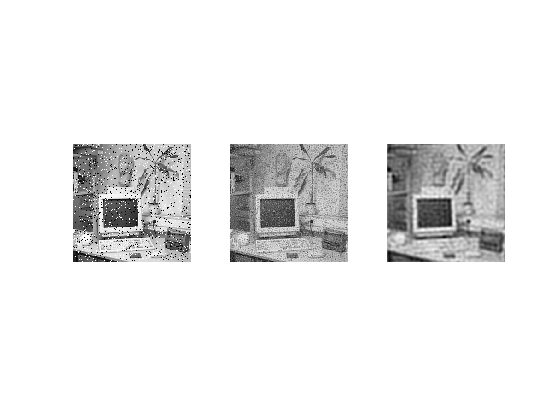


figure(37)
subplot(1,3,1);
showgrey(sap);
subplot(1,3,2);
showgrey(sap_lowpass);
subplot(1,3,3);
showgrey(ideal(sap,0.1));

The following code deals with Question 19-20(Smoothing and Subsampling)

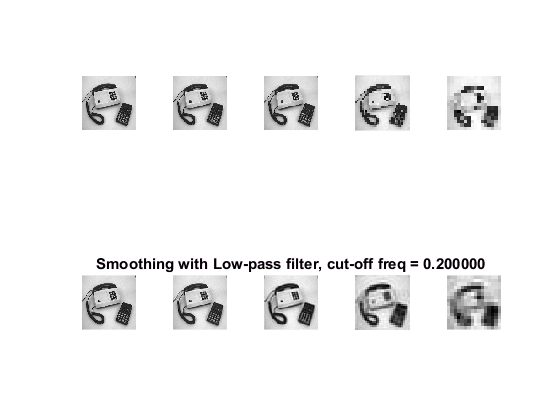

figure(38)
q19(1,0.2)

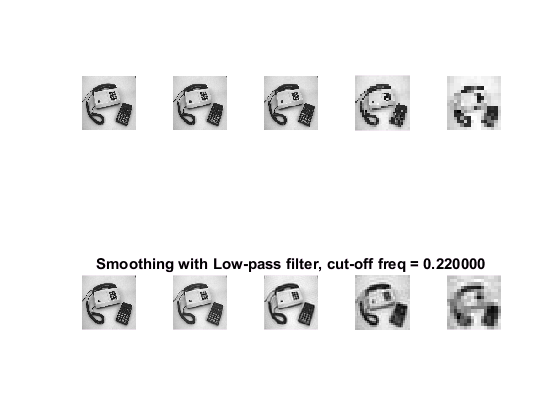


figure(39)
q19(1,0.22)

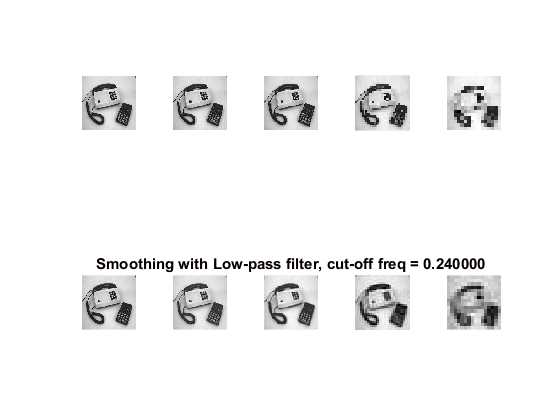


figure(40)
q19(1,0.24)

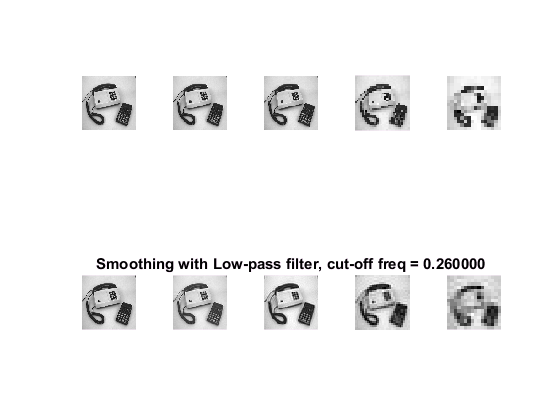


figure(41)
q19(1,0.26)

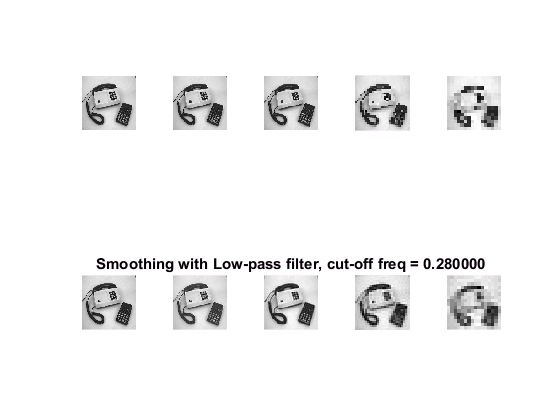


figure(42)
q19(1,0.28)

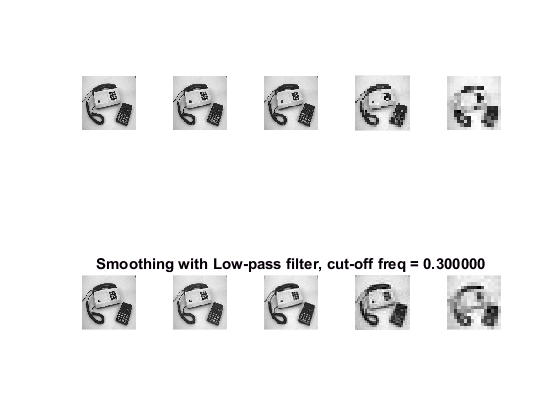


figure(43)
q19(1,0.30)

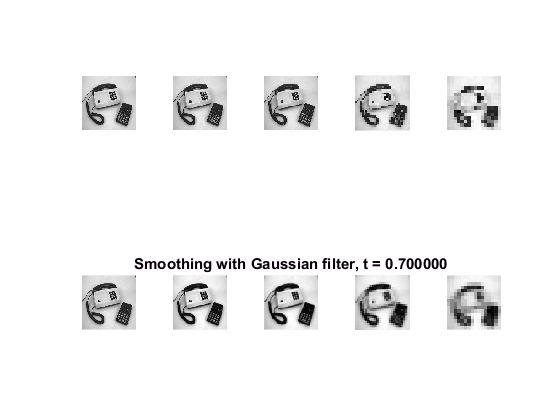


figure(44)
q19(2,0.7)

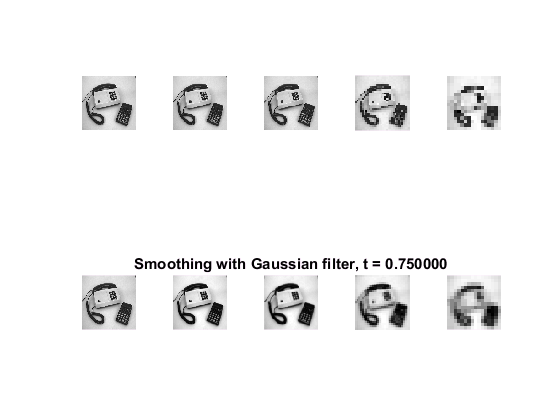


figure(45)
q19(2,0.75)

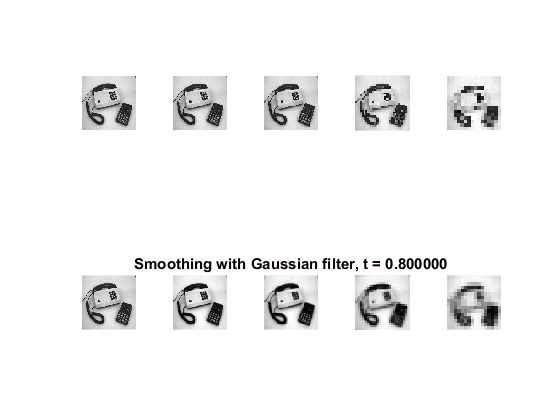


figure(46)
q19(2,0.80)

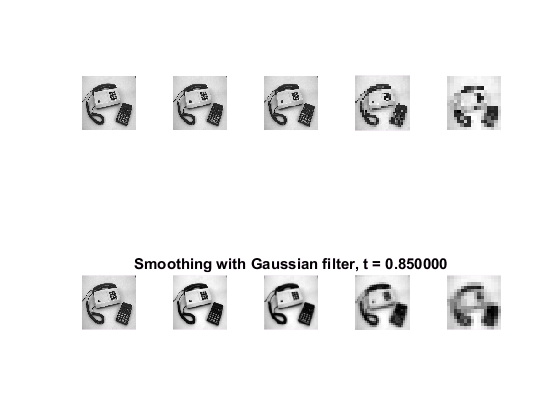


figure(47)
q19(2,0.85)

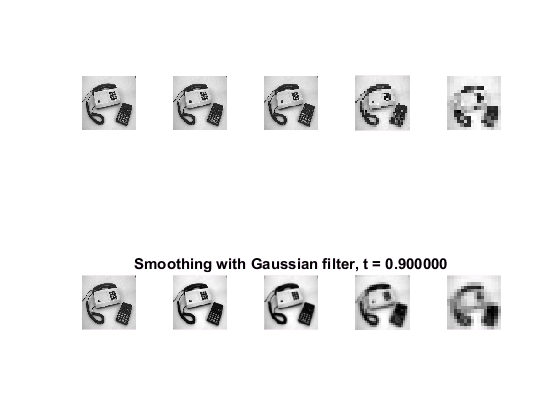


figure(48)
q19(2,0.9)

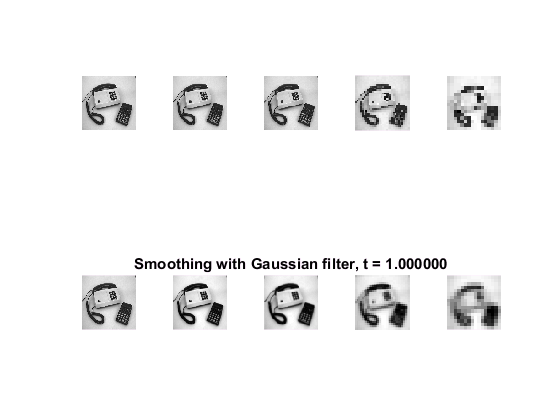


figure(49)
q19(2,1.0)

# END OF LIVE SCRIPT